# The Taylor model: external information and leaders

Taylor (1968) added external communication sources -- mass media, institutions, static leaders -- to the Abelson model:

NOTE. The tutorial prints this as "+ u" in Eq. (15), but consistency with Eq. (14) and with the limit formula of Theorem 18 (which contains Gamma^11) requires the input to be Gamma*u. This project implements Gamma*u.

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

NDS opinion-dynamics library added to the path.
Project root: /Users/llp/Desktop/NDS_Project


## From sources to prejudices

The original form has m external sources acting through a persuasibility matrix B. `taylor_reduce` collapses them into one prejudice per agent.

B = [1 3; 0 0; 2 2; 0 1];      % 4 agents, 2 sources
s = [10; 20];                  % the two source opinions
[gamma, u] = taylor_reduce(B, s);

fprintf('exposure gamma : %s\n', mat2str(gamma.'));

exposure gamma : [4 0 4 1]


fprintf('prejudice u    : %s\n', mat2str(round(u.', 4)));

prejudice u    : [17.5 0 15 20]


fprintf('agent 2 is free of external influence (gamma_2 = %g)\n', gamma(2));

agent 2 is free of external influence (gamma_2 = 0)


## Anchoring turns marginal stability into exponential stability

L is a SINGULAR M-matrix, so the pure Abelson model is only marginally stable. Adding Gamma makes L + Gamma NONSINGULAR exactly when every agent is P-dependent, and the system acquires a unique equilibrium.

net = make_ring(6, 'SelfWeight', 0.2);

unanchored = taylor_matrices(net.A, 0);
anchored   = taylor_matrices(net.A, [1 0 0 0 0 0]);

fprintf('\nno anchor : Hurwitz %d, min Re(eig) = %.6f\n', ...
    unanchored.isHurwitz, unanchored.minRealPart);


no anchor : Hurwitz 0, min Re(eig) = -0.000000


fprintf('one anchor: Hurwitz %d, min Re(eig) = %.6f\n', ...
    anchored.isHurwitz, anchored.minRealPart);

one anchor: Hurwitz 1, min Re(eig) = 0.111055


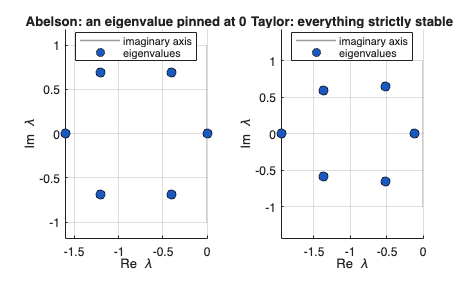


figure;
tl = tiledlayout(1, 2);
plot_spectrum(-unanchored.M, 'Domain', 'continuous', 'Axes', nexttile(tl), ...
    'Title', 'Abelson: an eigenvalue pinned at 0');
plot_spectrum(-anchored.M, 'Domain', 'continuous', 'Axes', nexttile(tl), ...
    'Title', 'Taylor: everything strictly stable');

## P-dependence: the mirror image of the consensus condition

For CONSENSUS you need one agent that reaches everyone. For STABILITY you need the ANCHOR SET to reach everyone. Same reachability machinery, dual roles.

gammaOne = [1 0 0 0 0 0].';
[~, info] = p_dependence(net.W, gammaOne > 0);
fprintf('\nanchors        : %s\n', mat2str(info.anchored));


anchors        : 1


fprintf('P-dependent    : %s\n', mat2str(info.pDependent));

P-dependent    : [1 2 3 4 5 6]


fprintf('P-independent  : %s\n', mat2str(info.pIndependent));

P-independent  : zeros(1,0)


fprintf('all dependent  : %d  -> asymptotically stable\n', info.allDependent);

all dependent  : 1  -> asymptotically stable


## Two leaders: opinions settle inside their convex hull

Because the limit map is stochastic, final opinions are convex combinations of the prejudices. This is the containment property: nothing escapes the hull of what anchors the group.

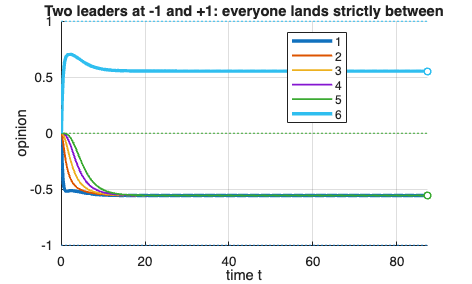

gammaTwo = [2; 0; 0; 0; 0; 2];
uTwo     = [-1; 0; 0; 0; 0; 1];
tm = taylor_matrices(net.A, gammaTwo);
T = 30 / tm.minRealPart;

res = sim_taylor(net, gammaTwo, uTwo, zeros(6, 1), linspace(0, T, 400));
figure; plot_opinions(res, 'Prejudice', uTwo, 'Highlight', [1 6], ...
    'Title', 'Two leaders at -1 and +1: everyone lands strictly between');


fprintf('\nlimit  : %s\n', mat2str(round(res.xinf.', 4)));


limit  : [-0.5556 -0.5556 -0.5556 -0.5556 -0.5556 0.5556]


fprintf('inside [%g, %g] : %d\n', min(uTwo), max(uTwo), ...
    all(res.xinf >= min(uTwo)) && all(res.xinf <= max(uTwo)));

inside [-1, 1] : 1


## The limit forgets the initial condition

When every agent is P-dependent the equilibrium depends only on the prejudices. The group forgets where it started and remembers only what anchors it.

starts = {zeros(6,1), 10*ones(6,1), (1:6).'};
fprintf('\n%-22s %s\n', 'initial condition', 'limit');


initial condition      limit


for k = 1:numel(starts)
    r = sim_taylor(net, gammaTwo, uTwo, starts{k}, linspace(0, T, 200));
    fprintf('%-22s %s\n', mat2str(starts{k}.'), mat2str(round(r.xinf.', 4)));
end

[0 0 0 0 0 0]          [-0.5556 -0.5556 -0.5556 -0.5556 -0.5556 0.5556]
[10 10 10 10 10 10]    [-0.5556 -0.5556 -0.5556 -0.5556 -0.5556 0.5556]
[1 2 3 4 5 6]          [-0.5556 -0.5556 -0.5556 -0.5556 -0.5556 0.5556]


## Convergence rate: the grounded Laplacian

The smallest eigenvalue of L + Gamma sets the rate. Stronger anchoring means faster settling -- and also a narrower spread at equilibrium.

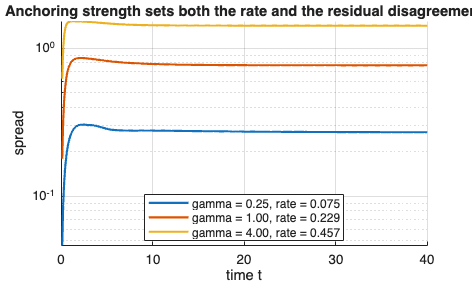

figure; hold on; grid on;
for g = [0.25 1 4]
    tmg = taylor_matrices(net.A, g * [1; 0; 0; 0; 0; 1]);
    rg = sim_taylor(net, g * [1; 0; 0; 0; 0; 1], uTwo, zeros(6,1), linspace(0, 40, 400));
    spread = max(rg.X, [], 1) - min(rg.X, [], 1);
    semilogy(rg.t, spread, 'LineWidth', 1.6, ...
        'DisplayName', sprintf('gamma = %.2f, rate = %.3f', g, tmg.minRealPart));
end
set(gca, 'YScale', 'log'); xlabel('time t'); ylabel('spread');
title('Anchoring strength sets both the rate and the residual disagreement');
legend('Location', 'best'); hold off;